# LAB 5: DESIGN OF SPEED ESTIMATOR for DC MOTOR

%---------------------------------------
% Fill in your group number.
GroupNumber = 0;
% Fill in your student Name and ID.
Students(1).Name = '';
Students(1).ID = '';
Students(2).Name = '';
Students(2).ID = '';
%---------------------------------------

## **0. Objectives**

In this lab, we will use observations from the DC Motor to estimate the angular velocity and the current of the DC Motor. First, using the DC Motor state space model, we design an estimator gain for the discrete time system such that the estimated value follow the states. Second, we run the motor with a pre-defined input (open loop and closed loop) and estimate the speed as well as the current, observing only angular velocity as the output.

Follow carefully step 1, 2 and 4 in the guide `QNET DC Motor Quick Start Guide.pdf` to make sure your Qnet DC Motor is setup correctly. You should put the file `QnetDCMotor.m` in the same folder as the livescript. To initiate a connection with the hardware, run the following (You can ignore the warnings, but you shouldn't have any errors)

Motor = QnetDCMotor();

## **1. A State-Space Representation of DC Motor**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown in the following

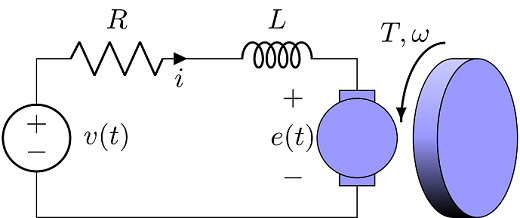

We can model the DC motor using the armature current $i$ and the angular speed $\omega$. The dynamics of the DC motor are given by the following two coupled differential equations:


$$ J \frac{d \omega}{dt} + b \omega = K_t i $$



$$ L \frac{d i}{dt} + R i = v - K_e \omega $$


where the parameters are defined as follow

Param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
Param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
Param.L = 0.018; % Electric inductance (H)
Param.R = 8.4; % Terminal resistance (Ohm)
Param.J = 2e-05; % Rotor moment of inertia (kg.m2)
Param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

From these differential equations we can represent the DC Motor model by the following state-space representation


$$ \frac{d}{dt}x(t) = \pmatrix{ -\frac{b}{J} & \frac{K_t}{J} \cr
-\frac{K_e}{L} & -\frac{R}{L} } x(t) + \pmatrix{ 0 \cr \frac{1}{L} } v(t)
$$


where $v(t)$ is the voltage and the state vector contains the angular velocity $\omega(t)$ and the current $i(t)$


$$ x(t) = \pmatrix{ \omega(t) \cr i(t) } $$


Thus, the state-space matrices of the DC Motor model can be written in `MATLAB` as

A = [-Param.b / Param.J, Param.Kt / Param.J; -Param.Ke / Param.L, -Param.R / Param.L];
B = [0; 1 / Param.L];
C = [1, 0];
D = 0;

## *Question 1 (1.5 mark)*

Using the the function `ss` construct the state-space representation in `MATLAB` of the continous time and the discrete time system. For the dicrete time state space use `c2d(sys,Ts,method)` with the **zero order hold (zoh)** method and $T_s = dt = 0.01$.

[Answer here]

Go = [];
Go_d = [];

## *Question 2 (1 mark)*

Using `MATLAB`, compute the eigenvalues of the observability matrix of both the continuous time and the discrete time systems? Based on the eigenvalues, are both of the systems observable?

[Answer here] Eigen values of [C, C A] for Go

% Eigen values of [C, C A] for Go_d

% Are the systems observable ?

## **2. State Estimator Design**

Knowing the system state is necessary to solve many control problems; for example, stabilizing a system using state feedback. In most practical cases, the physical state of the system cannot be determined by direct observation. Instead, indirect effects of the internal state are observed by way of the system outputs. A simple example is that of vehicles in a tunnel: the rates and velocitis at which vehicles enter and leave the tunnel can be observed directly, but the exact state inside the tunnel can only be estimated. If a system is observable, it is possible to fully reconstruct the system state from its output measurements using the state observer.

In this lab, we assume that the full state feedback is not available and only the angular speed ($\omega$) is available. In other words, we have


$$y(t) = \omega(t)$$


We wish to use output feedback controller to meet the following tracking objective:

- Overshoot less than 10%.

- 5% settling time of less than 0.2 second.

- Steady state error less than 5%.

## *3. Open Loop Observer Design*

In this section we want to use the estimator designed above to estimate the states of the DC motor in an open loop structure. The representation of an open loop system with an estimator is given as follows:

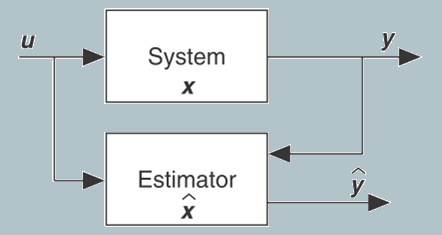

As you see, the estimator is like a parallel system that receives the input and output of the system and generates an estimate of the states.

Assuem that an input


$$ v(t) = N \omega_{ref}(t) $$


is given to the motor, where $N$is the open-loop DC gain you and $\omega_ref(t)$ is as follows:

T = 10; % Simulation duration
dt = 0.01; % Simulation step time
time = 0:dt:T; % Time array
TStart = 5; % Step start
wRef = zeros(size(time));
wRef(time < TStart) = 25;
wRef(time >= TStart) = 75;

figure(1); clf;
title(sprintf('Group %d - Open-loop tracking experiment', GroupNumber));
plot(time, wRef)
legend('Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([0, T])
ylim([0, 100])
grid on

We will generate a set of measurements for angular velocity from the DC Motor. For this we run the following experiment

dcGainOL = C * (-A)^(-1) * B;

Motor.reset();
for n = 1:length(time)
    t_ = time(n);
    v_ = wRef(n) / dcGainOL; % Genrate the input
    Motor.drive(v_, t_, dt);
end
Motor.off();

% Get results of driving Qnet DC Motor
v = Motor.voltage(0, T);
i = Motor.current(0, T);
w = Motor.velocity(0, T);

Recall that the Luenberger observer equation in continuous time is


$$ \frac{d}{dt} \hat{x}(t) = A\hat{x}(t) + B u(t) + L (y(t) - \hat{y}(t))
$$


Equivalently we can write the same equation in discrete time:


$$ \hat{x}(n+1) = A_d \hat{x}(n) + B_d u(n) + L_d (y(n) - \hat{y}(n))$$


where ($A_d$, $B_d$) are discrete form of ($A$, $B$), and $L_d$ is the equivalent Luenberger gain of $L$ in discrete time.

If $L$ is a Luenberger gain for ($A$, $C$) which places poles ($p_1$, $p_2$) . The equivalent $L_d$ gain will place the discrete poles ($\exp(p_1 T_s)$, $\exp(p_2 T_s)$) for the discrete system ($A_d$, $C_d$) .

In `MATLAB`, the function `place` is designed for choosing the controller gain $K$. Yet by using the duality between choosing controller gain $K$ and choosing estimator gain $L$ we can use `place` to identify the gain $L$.

## *Question 3 (4.5 marks)*

Complete the following code to design a state estimator for the DC Motor. Choose $L$ such that the closed loop eigenvalues of the estimation error are

- 
$$P_{1,2} = -10 \pm 10 j$$


- 
$$P_{1,2} = -100 \pm 100 j$$


- 
$$P_{1,2} = -500 \pm 500 j$$


% 1.
p1 = -10 + 10j;
p2 = -10 - 10j;

% [Answer Here] Find the gain Ld (use place)

Ld1 = [];


% Simulate state estimation
xHat1 = zeros(2, length(time));
for n = 1:length(time) - 1
    v_ = wRef(n) / dcGainOL;
    % [Answer Here] Write the estimator dynamics here

    xHat1(:, n+1) = [0; 0];

end

% calculate error between estimated and measured angular velocity
error_w_1 = sum(abs(w'-xHat1(1, :))) / length(time)

% [Answer Here] Do the same for 2. and 3.

For the best gain, complete the code to plot $e(t) = x(t) - \hat{x}(t)$ versus time.

% Plot results
figure(2); clf;

subplot(2, 1, 1)
title(sprintf('Group %d - speed true and estimated state', GroupNumber));
% [Answer Here] Superpose measured and estimated angular velocity

legend('Measured angular velocity (rad/s)', ...
    'Estimated angular velocity (rad/s)', ...
    'location', 'southeast');
xlim([0, T])
grid on

subplot(2, 1, 2)
% [Answer Here] Plot the error between measured and estimated angular
% velocity

legend('Error in angular velocity estimation', 'location', 'best');
xlim([0, T])
grid on

%%===================
figure(3); clf;

subplot(2, 1, 1)
title(sprintf('Group %d - Current true and estimated state', GroupNumber));
% [Answer Here] Superpose measured and estimated current

legend('Measured current (A)', ...
    'Estimated current (A)', ...
    'location', 'northwest');
xlim([0, T])
grid on

subplot(2, 1, 2)
% [Answer Here] Plot the error for current here

legend('Error in current estimation', 'location', 'best');
xlim([0, T])
grid on

## *Question 4 (1 marks)*

1. A discrete observer is called asymptotically stable if the observer error $e(n) = x(n) - \hat{x}(n)$ converges to zero when $n \to \infty$. For a discrete Luenberger observer, the observer error satisfies $e(n+1) = (A_d - L_d C_d) e(n)$ and therefore the Luenberger observer for this discrete-time system is asymptotically stable if and only if all of the eigenvalues of $(A_d - L_d C_d)$ are all inside the unit circle. Compute the eigenvalues of $(A_d - L_d C_d)$ in discrete time and determine whether the observer is asymptotically stable or not.

[Answer here]

2. Based on the plot of the error in question 1, does the error go to zero? Does this confirm the asymptotical stability of the observer? If not justify your answer.

% [Answer here]

## **3. Closed-loop State Estimator for Speed Control**

In this section, we want to use the estimated states with a state feedback controller to track the reference input defined previously in section 2, while satisfying the three specifications. The state feedback input to the system is


$$v(t) = N \omega_{ref} - K x(t)$$


Because the observation of the system is not complete and we don't have access to the full state of the system, we use the following control law instead:


$$v(t) = N\omega_{ref} - K \hat{x}(t)$$


where $K$ and $N$ are computed to satisfy the specifications.

ts = 0.2;
Mp = 0.1;
xi = -log(Mp) / sqrt(pi^2+log(Mp)^2);
wn = 3 / (ts * xi);

p1d = -wn * (xi + sqrt(1-xi^2) * 1i)
p2d = -wn * (xi - sqrt(1-xi^2) * 1i)

Kd = place(Go_d.A, Go_d.B, [exp(p1d*dt), exp(p2d*dt)]);
Nd = 1 / (Go_d.C * (eye(2) - Go_d.A + Go_d.B * Kd)^(-1) * Go_d.B);

## *Question 5 (2 marks)*

- Use the estimator designed above to estimate the states and use the estimated states with the state feedback controller identified in Lab 04 to track the step reference defined in the beginning of this lab.

% Drive motor
Motor.reset();

xHat = zeros(2, length(time));
for n = 1:length(time)
    t_ = time(n);
    w_ = Motor.velocity(t_);
    if (t_ < TStart)
        v_ = wRef(n) / dcGainOL;
    else
        v_ = Nd * wRef(n) - Kd * xHat(:, n);
    end
    if n < length(time)
        % [Answer Here] write the dynamics of the estimator here

    end
    Motor.drive(v_, t_, dt);
    
end
Motor.off();

% Get results of driving Qnet DC Motor
v = Motor.voltage(0, T);
i = Motor.current(0, T);
w = Motor.velocity(0, T);

Plot results

figure(4); clf;

subplot(2, 1, 1)
title(sprintf('Group %d - speed true and estimated state', GroupNumber));
% [Answer Here] Superpose measured and estimated angular velocity

legend('Measured angular velocity (rad/s)', ...
    'Estimated angular velocity (rad/s)', ...
    'location', 'southeast');
xlim([0, T])
grid on

subplot(2, 1, 2)

% [Answer Here] Plot the error between measured and estimated angular
% velocity

legend('Error in angular velocity estimation', 'location', 'best');
xlim([0, T])
grid on

%%===================
figure(5); clf;

subplot(2, 1, 1)
title(sprintf('Group %d - Current true and estimated state', GroupNumber));
% [Answer Here] Superpose measured and estimated current

legend('Measured current (A)', ...
    'Estimated current (A)', ...
    'location', 'northwest');
xlim([0, T])
grid on

subplot(2, 1, 2)
% [Answer Here] Plot the error for current here

legend('Error in current estimation', 'location', 'best');
xlim([0, T])
grid on

2 . How these results compare XXXXXXX, justify your answer.

[Answer here]